# Explore $F_{\mathrm{mag}}$ vs Stroke measurement data

- REF_01:  [http://solenoidcity.com/solenoid/tubular/s-41-300hp2.htm](http://solenoidcity.com/solenoid/tubular/s-41-300hp2.htm) 

- REF_02:  [http://solenoidcity.com/solenoid/tubular/s-41-300h.pdf](http://solenoidcity.com/solenoid/tubular/s-41-300h.pdf) 

         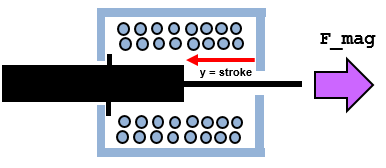

We'll use a MATLAB class to act as a 'Data Dictionary" for our solenoid datasheet data:

my_sol_OBJ = bh_solenoid

my_sol_OBJ =   bh_solenoid with properties:

               mass: 0.6000
            damping: 5.3229
          stiffness: 17
        volts_rated: 7.6000
      current_rated: 4
         resistance: 1.9000
    F_mag_datasheet: [13×1 double]
      y_m_datasheet: [13×1 double]
       MAX_y_airgap: 0.0600
                 C1: 20.4094
                 C2: 67.0984
                 C3: 0.7548


Get the datasheet data:

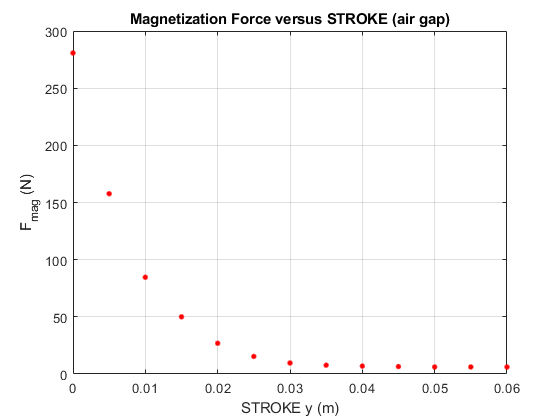

[F_mag, y_m]  = my_sol_OBJ.get_Fmag_vs_stroke_datasheet(true);

Recall that our Magnetization force is related to the Solenoid induction via the expression:

- $F_{\text{mag}} =\text{ }-1\ldotp \frac{1}{2}\text{ }\ldotp i^2 \ldotp \frac{\partial L\left(y\right)}{\partial y}$            where "*y*" is the air gap distance.

And that we found this to be:

- 
$$F_{\text{mag}} =\text{ }\text{ }\frac{1}{2}\ldotp i^2 \ldotp \frac{C_1 }{{\left(C_2 \ldotp y\text{ }+C_3 \right)}^2 }$$


The specification data sheet for our solenoid is here:

- [http://solenoidcity.com/solenoid/tubular/s-41-300h.pdf](http://solenoidcity.com/solenoid/tubular/s-41-300h.pdf) 

and note the following from this data sheet:

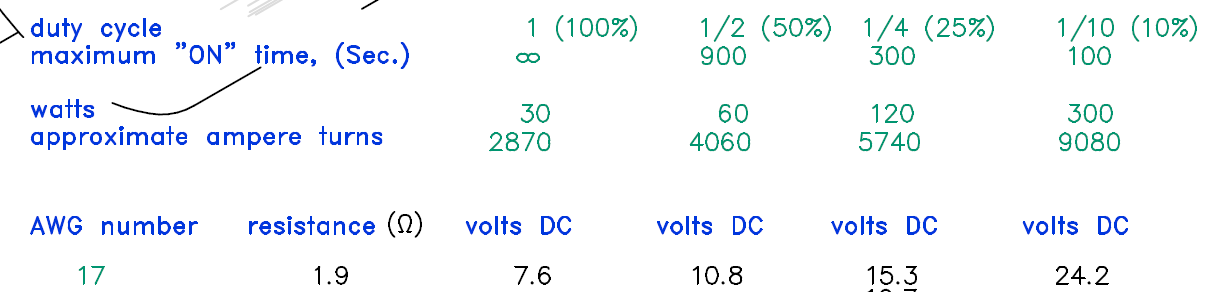

So? - So let's say that the current that was applied to produce the "$F_{\mathrm{mag}} \text{ }\mathrm{vs}\text{ }\mathrm{STROKE}$" data was:

- 
$$i=\frac{7\ldotp 6}{1\ldotp 9}=4\text{ }\mathrm{amps}\text{ }$$


So for this particular solenoid our Magnetic force equation is:

- $F_{\text{mag}} =\text{ }\text{ }\frac{1}{2}\ldotp i^2 \ldotp \frac{C_1 }{{\left(C_2 \ldotp y\text{ }+C_3 \right)}^2 }$    =    $\frac{1}{2}\ldotp 4^2 \ldotp \frac{C_1 }{{\left(C_2 \ldotp y\text{ }+C_3 \right)}^2 }$   =   $8\ldotp \frac{C_1 }{{\left(C_2 \ldotp y\text{ }+C_3 \right)}^2 }$

When we do a curve fit through our measurement data, we get the following:

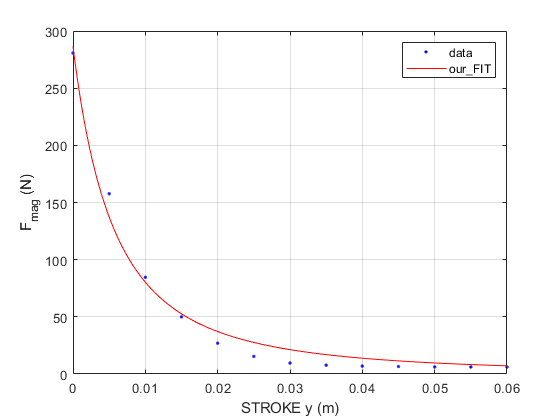

ans =      General model:
     ans(y) = bh_func_calc_my_F(C1,C2,C3,my_i,y)
     Coefficients (with 95% confidence bounds):
       C1 =       20.41  (-3.324e+08, 3.324e+08)
       C2 =        67.1  (-5.464e+08, 5.464e+08)
       C3 =      0.7548  (-6.147e+06, 6.147e+06)

my_sol_OBJ.do_curve_fit(true)

## Visualize the Magnetic Force:

We've defined the expression for Magnetic force into a function:

dbtype   bh_func_calc_my_F.m


1     function my_F = bh_func_calc_my_F(C1,C2,C3, i, y)
2              my_F = 0.5 * (i^2) * C1 ./ ( (C2*y + C3).^2 );
3     end


So using this, we have:

[C1,C2,C3] = my_sol_OBJ.get_the_C_coeffs()

C1 = 20.4094

C2 = 67.0984

C3 = 0.7548

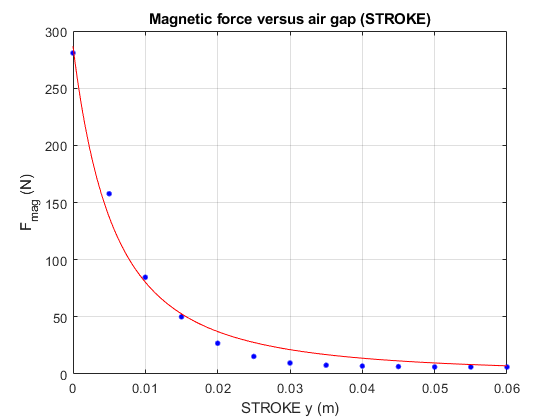

i          = my_sol_OBJ.current_rated;

fit_Fmag = @(y) bh_func_calc_my_F(C1,C2,C3, i, y);

figure;
  plot(y_m, F_mag, 'b.', 'MarkerSize', 12);
    grid on, xlabel('STROKE y (m)'); ylabel('F_{mag} (N)')
    hold on
  tmp_ym = 0:0.0001:0.06;
  plot(tmp_ym, fit_Fmag(tmp_ym), 'r-');
    title('Magnetic force versus air gap (STROKE)')

## So visualize the Inductance:

We've defined the expression for inductance into a function:

dbtype   bh_func_calc_my_L.m


1     function my_L = bh_func_calc_my_L(C1,C2,C3, y)
2              my_L =  (C1/C2) ./ (C2*y + C3);
3     end


So using this, we have:

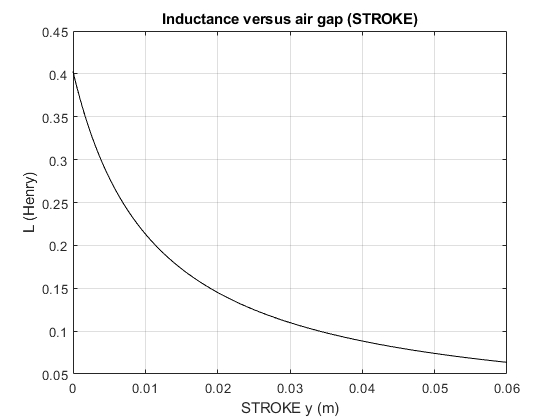

fit_L    = @(y) bh_func_calc_my_L(C1,C2,C3, y);

figure;
  tmp_ym = 0:0.0001:0.06;
  plot(tmp_ym, fit_L(tmp_ym), 'k-');
  title('Inductance versus air gap (STROKE)')
  grid on, xlabel('STROKE y (m)'); ylabel('L (Henry)')

## Zoom in on the magnetic Force:

The plunger needs to overcome any load over its full stroke length. So let's zoom in and explore this:

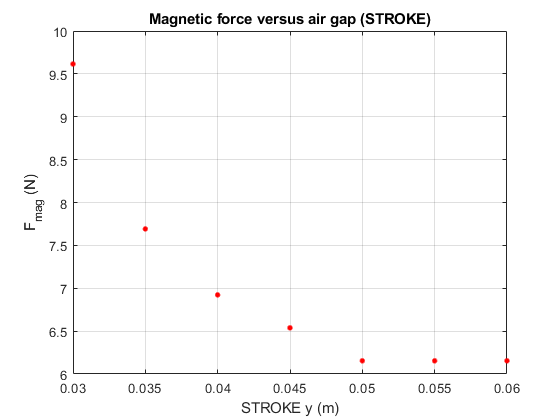

figure;
plot(y_m, F_mag, 'r.', 'MarkerSize', 12);
grid on, xlabel('STROKE y (m)'); ylabel('F_{mag} (N)'); xlim([0.03 0.06])
title('Magnetic force versus air gap (STROKE)')

So looks like we need to keep the load at 6 NEWTONS or less.